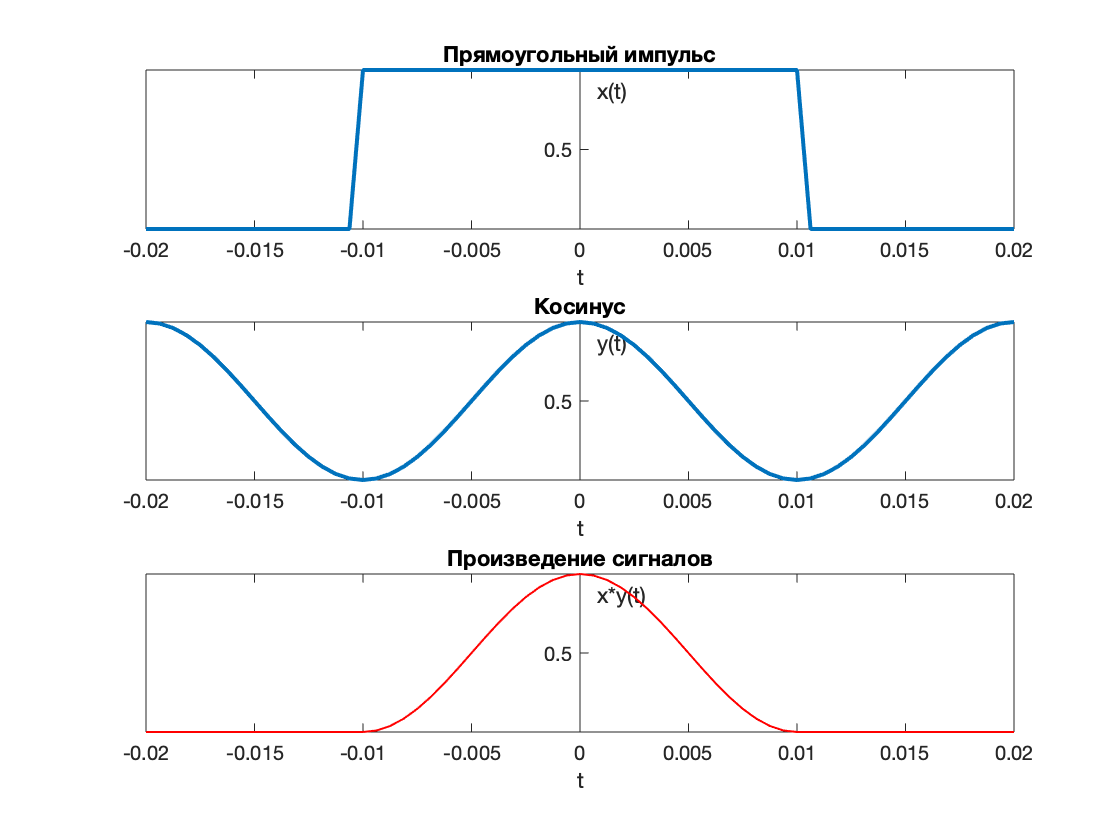

f0=1*10^2;      
T=1/f0;         
f=linspace(-4*f0, 4*f0, 65);
t=linspace(-2*T, 2*T, 65);

x=[zeros(1,(numel(t)-1)/4), ones(1,((numel(t))-1)/2+1), zeros(1,(numel(t)-1)/4)]; 
y = (1 + cos(pi.*t./T))./2;

dt = 0.000002;

figure;
subplot1 = subplot(3,1,1); plot(t, x,'LineWidth',2);
set(subplot1,'XAxisLocation','origin','YAxisLocation','origin');
xlabel('t'); ylabel('x(t)'); title('Прямоугольный импульс');
subplot2 = subplot(3,1,2); plot(t, y, 'LineWidth',2);
set(subplot2,'XAxisLocation','origin','YAxisLocation','origin');
xlabel('t'); ylabel('y(t)'); title('Косинус');
subplot3 = subplot(3,1,3); plot(t, x.*y, 'r', 'LineWidth',1);
set(subplot3,'XAxisLocation','origin','YAxisLocation','origin');
xlabel('t'); ylabel('x*y(t)'); title('Произведение сигналов');

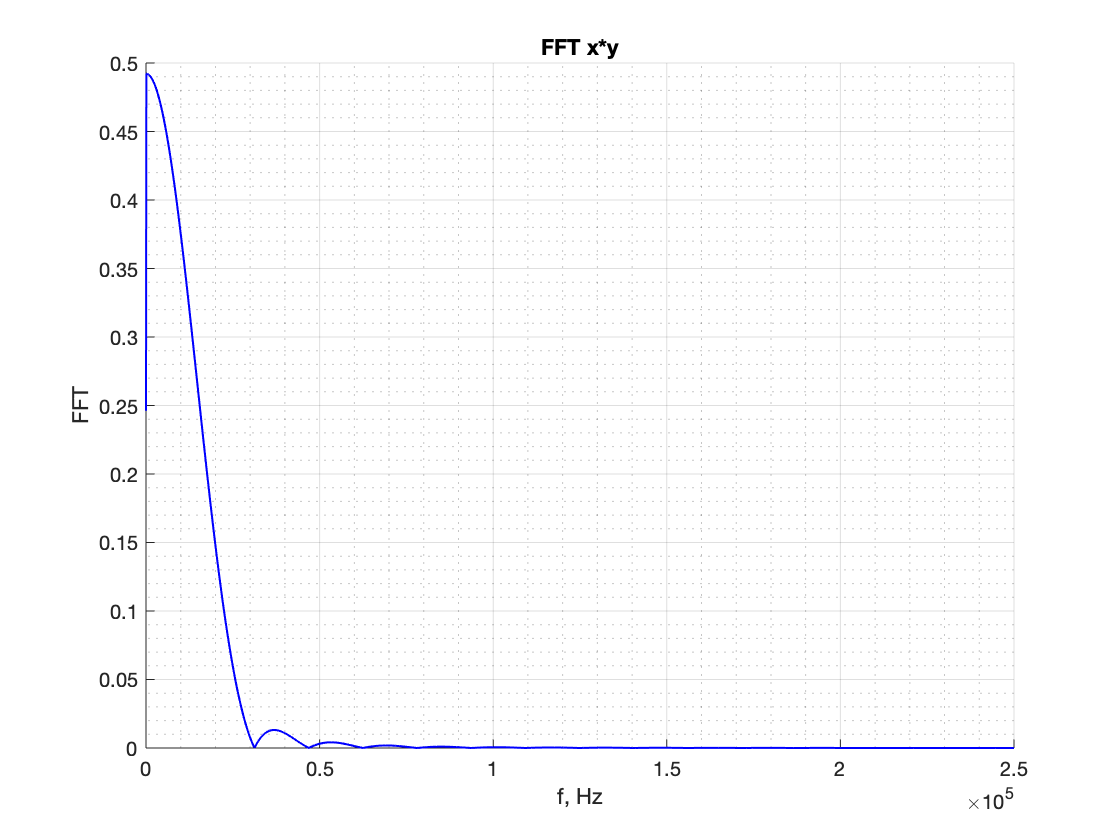


[fftAmp2, fftF2] = analyzeFFT(x.*y, dt);
%Спектры результирующих сигналов
figure('name', 'FFT'); 
grid on;
grid minor;
hold on;
plot(fftF2, abs(fftAmp2), 'b', 'LineWidth', 1);
hold off;
xlabel('f, Hz'); ylabel('FFT');
title('FFT x*y');

Спектр косинуса (другой способ)

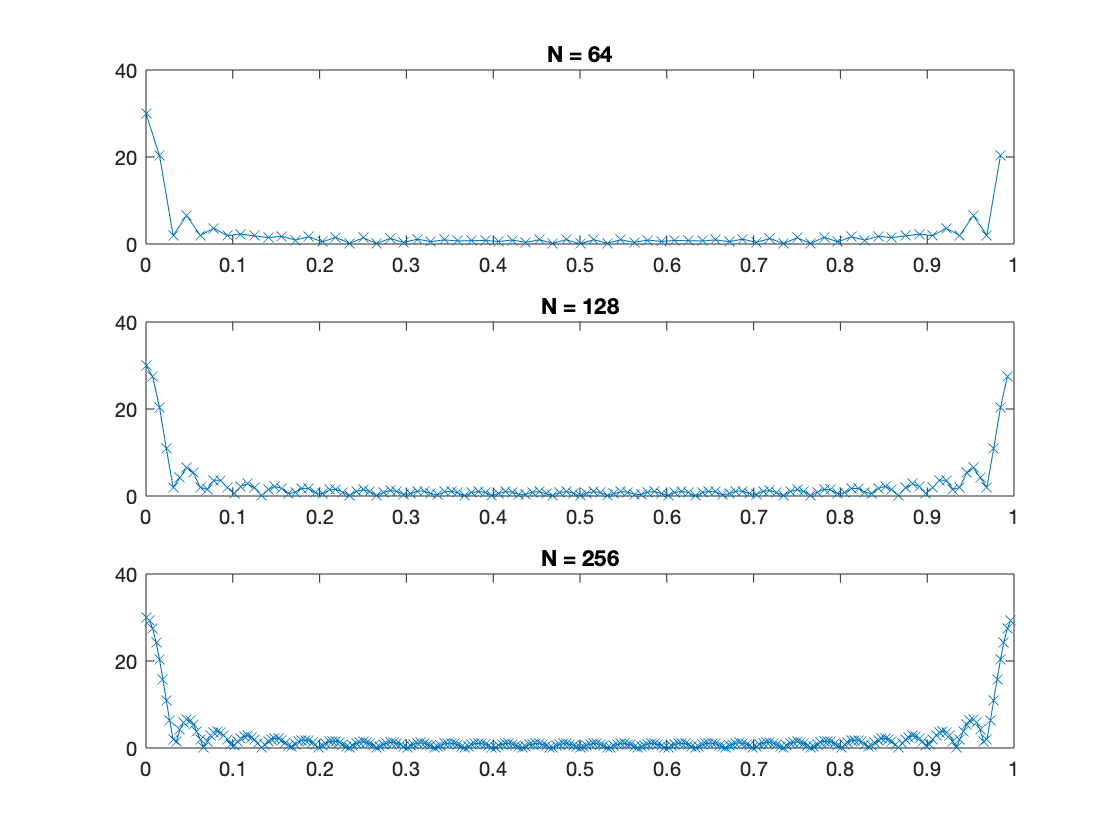


n = [0:29];
x1 = (1 + cos(pi.*n./T))./2;

N1 = 64;
N2 = 128;
N3 = 256;
X1 = abs(fft(x1,N1));
X2 = abs(fft(x1,N2));
X3 = abs(fft(x1,N3));

F1 = [0 : N1 - 1]/N1;
F2 = [0 : N2 - 1]/N2;
F3 = [0 : N3 - 1]/N3;

%Спектры результирующих сигналов
figure;
subplot(3,1,1)
plot(F1,X1,'-x'),title('N = 64'),axis([0 1 0 40])
subplot(3,1,2)
plot(F2,X2,'-x'),title('N = 128'),axis([0 1 0 40])
subplot(3,1,3)
plot(F3,X3,'-x'),title('N = 256'),axis([0 1 0 40])